%% Parameter

m = 2000;       % Masse [kg]
J = 4000;       % Massenträgheitsmoment Gierbewegung [kgm²]
lv = 1.43;      % Schwerpunktabstand zur Vorderachse [m]
lh = 1.4;       % Schwerpunktabstand zur Hinterachse [m]
cv = 70000;     % Schräglaufsteifigkeit Vorderachse [N/rad]
ch = 140000;    % Schräglaufsteifigkeit Hinterachse [N/rad]

delta = deg2rad(5);   % Lenkwinkel [rad]

%% Suchintervall für Geschwindigkeit (m/s)
v_min = 1;     % [m/s]
v_max = 60;    % [m/s] (≈ 216 km/h)

%% Optimierung
obj = @(v) abs(beta_stationary(v,m,J,lv,lh,cv,ch,delta));  % Ziel: |beta_inf|

opts = optimset('TolX',1e-8,'Display','off');
[v_opt, fval] = fminbnd(obj, v_min, v_max, opts);

%% Ergebnisse am Optimum
[beta_inf, psi_dot_inf] = stationary_state(v_opt,m,J,lv,lh,cv,ch,delta);

fprintf('v_opt = %.6f m/s (%.2f km/h)\n', v_opt, 3.6*v_opt);

v_opt = 13.926380 m/s (50.13 km/h)


fprintf('beta_inf = %.6f deg\n', rad2deg(beta_inf));

beta_inf = 0.000000 deg


fprintf('|beta_inf| = %.6f deg\n', rad2deg(abs(beta_inf)));

|beta_inf| = 0.000000 deg


fprintf('psi_dot_inf = %.6f deg/s\n', rad2deg(psi_dot_inf));

psi_dot_inf = 16.693258 deg/s


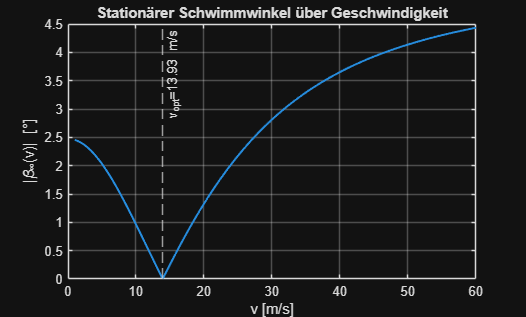


%% Visualisierung
v_plot = linspace(v_min, v_max, 300);
beta_plot = zeros(size(v_plot));
for i = 1:numel(v_plot)
    beta_plot(i) = rad2deg(beta_stationary(v_plot(i),m,J,lv,lh,cv,ch,delta));
end

figure;
plot(v_plot, abs(beta_plot), 'LineWidth', 1.5);
grid on;
xlabel('v [m/s]');
ylabel('|\beta_{\infty}(v)| [°]');
title('Stationärer Schwimmwinkel über Geschwindigkeit');
xline(v_opt, '--', sprintf('v_{opt}=%.2f m/s', v_opt));


%% ===== Funktionen =====

function beta_inf = beta_stationary(v,m,J,lv,lh,cv,ch,delta)
    % gibt den eingeschwungenen Schwimmwinkel (rad) zurück
    [beta_inf, ~] = stationary_state(v,m,J,lv,lh,cv,ch,delta);
end

function [beta_inf, psi_dot_inf] = stationary_state(v,m,J,lv,lh,cv,ch,delta)
    % Stationärer Zustand: x_inf = -A\(B*delta)

    A = [-(cv+ch)/(m*v),           (ch*lh - cv*lv)/(m*v^2) - 1;
          (ch*lh - cv*lv)/J,      -(cv*lv^2 + ch*lh^2)/(J*v)];

    B = [cv/(m*v);
         cv*lv/J];

    x_inf = -A \ (B*delta);      % numerisch stabiler als inv(A)

    beta_inf    = x_inf(1);      % [rad]
    psi_dot_inf = x_inf(2);      % [rad/s]
end